% fto_sim

corepath = pwd;
addpath([corepath,'/functions'])
ath = 0.05; % arbitrary threshold value for ttest
pth = 1 - ath; % permutation threshold
Nperm = 1000;

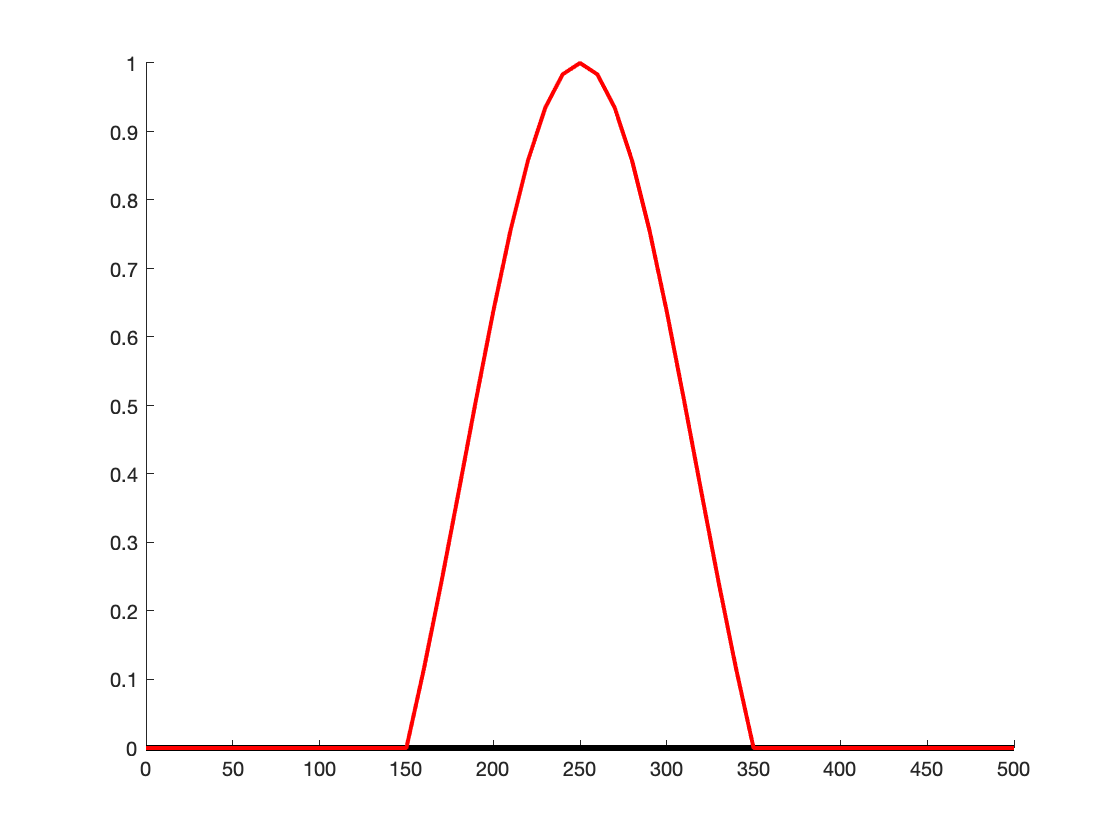

%% Make template

% true onset = 160 ms, F=17, max at F=26 
true_onset = 160;
Xf = 0:10:500;
Nf = length(Xf);
temp1 = zeros(1,Nf);
%temp2 = [zeros(1,15), linspace(0,1,21), ones(1,15)];
erp = normpdf(linspace(-1.5,1.5,21), 0, 1);
erp = erp - min(erp);
erp = erp / max(erp);
temp2 = [zeros(1,15), erp, zeros(1,15)];
% erp = minmax_scale(norm.pdf(np.linspace(-1.5, 1.5, 21)))

figure('Color', 'w', 'NumberTitle', 'off')
hold on
plot(Xf, temp1, 'k', 'LineWidth', 3)
plot(Xf, temp2, 'r', 'LineWidth', 2)

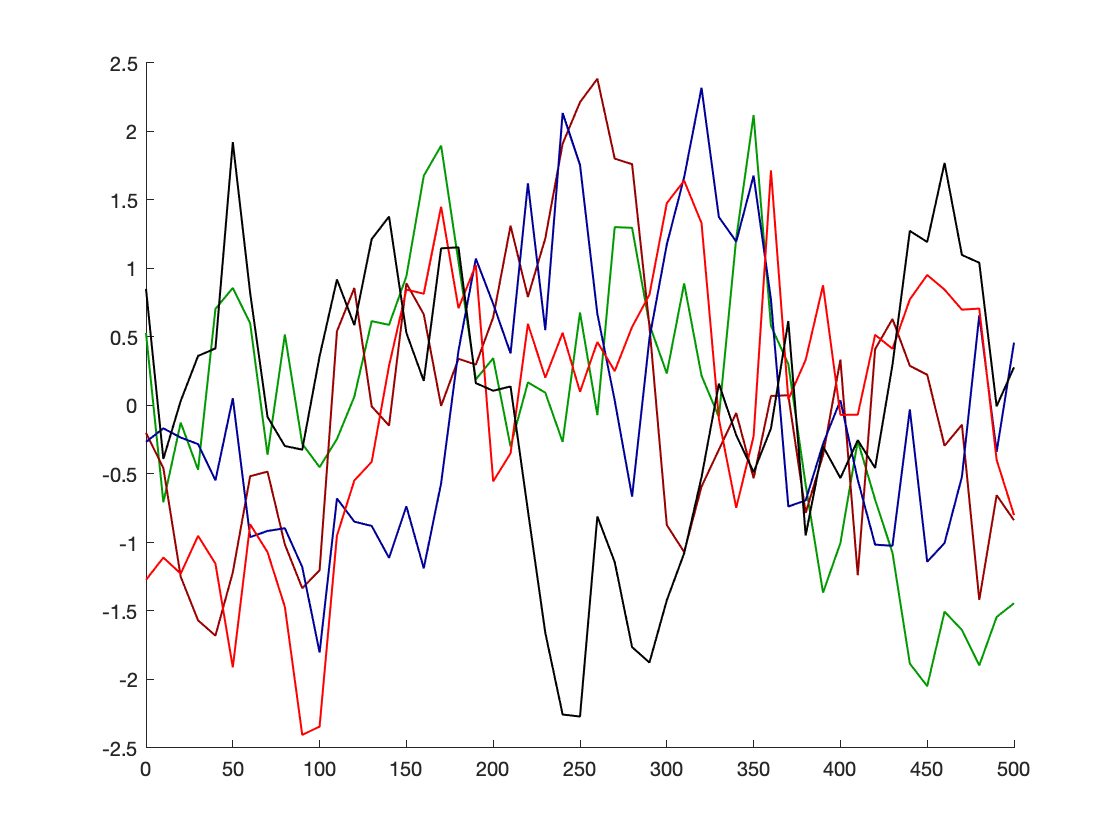

%% Illustrate noise

% Xf = 0:1:500; % 1000 Hz
Xf = 0:10:500; % 100 Hz
Nf = length(Xf);
outvar = 1;
gamma = 0.7;

figure('Color', 'w', 'NumberTitle', 'off')
hold on
% plot(Xf, pinknoise(Nf), 'r', 'LineWidth',2)
plot(Xf, one_over_f(gamma,Nf,outvar), 'Color', [0 0.6 0], 'LineWidth',1)
plot(Xf, one_over_f(gamma,Nf,outvar), 'Color', [0.6 0 0], 'LineWidth',1)
plot(Xf, one_over_f(gamma,Nf,outvar), 'Color', [0 0 0.6], 'LineWidth',1)
plot(Xf, one_over_f(gamma,Nf,outvar), 'Color', [1 0 0], 'LineWidth',1)
plot(Xf, one_over_f(gamma,Nf,outvar), 'Color', [0 0 0], 'LineWidth',1)

%% Template + noise -- one_over_f version

Nt = 50; % number of trials per condition
cond1 = zeros(Nf, Nt);
cond2 = zeros(Nf, Nt);

outvar = 0.1;
gamma = 0.7;

for T = 1:Nt
    cond1(:,T) = temp1 + (one_over_f(gamma,Nf,outvar)');
    cond2(:,T) = temp2 + (one_over_f(gamma,Nf,outvar)');
end

es = (mean(cond2, 2) - mean(cond1, 2)) ./ sqrt((var(cond1,0,2) + var(cond2,0,2)) / 2);
disp(['Mean effect size = ', num2str(round(mean(es(25:27)), 2))])

Mean effect size = 3.16


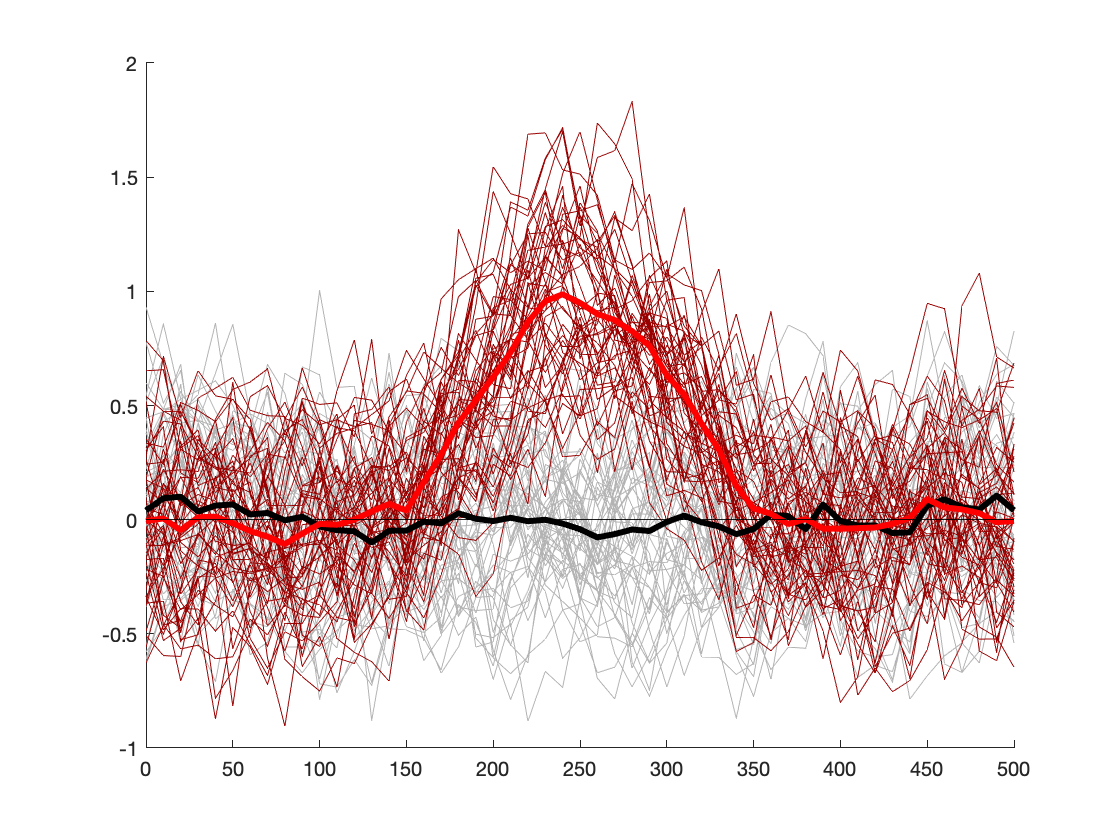


% Illustrate single-trials + means

figure('Color', 'w', 'NumberTitle', 'off')
hold on
plot(Xf, cond1, 'Color', [.7 .7 .7], 'LineWidth', 0.5)
plot(Xf, cond2, 'Color', [.6 0 0], 'LineWidth', 0.5)
plot(Xf, mean(cond1, 2), 'k', 'LineWidth', 3)
plot(Xf, mean(cond2, 2), 'r', 'LineWidth', 3)
plot(Xf, zeros(1, Nf), 'k')

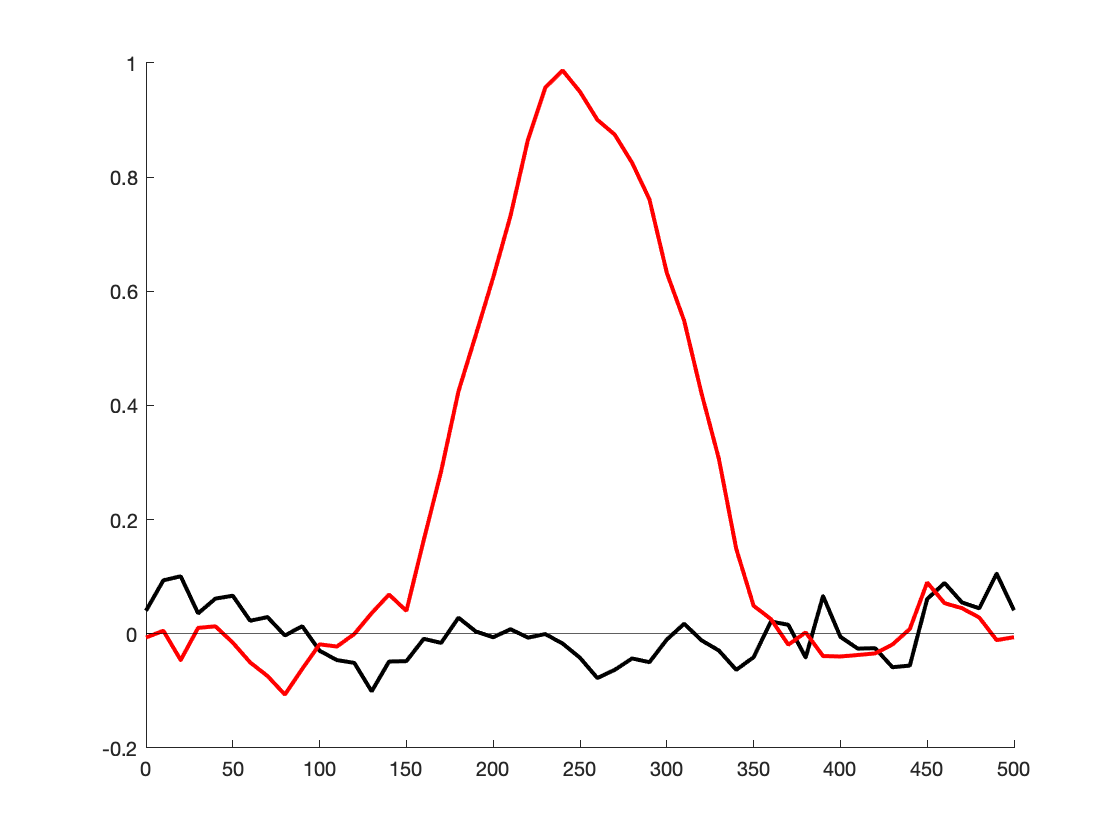

%% Illustrate means only

figure('Color', 'w', 'NumberTitle', 'off')
hold on
% plot(Xf, cond1, 'k', 'LineWidth', 1)
% plot(Xf, cond2, 'r', 'LineWidth', 1)
plot(Xf, mean(cond1, 2), 'k', 'LineWidth', 2)
plot(Xf, mean(cond2, 2), 'r', 'LineWidth', 2)
plot(Xf, zeros(1, Nf), 'k')

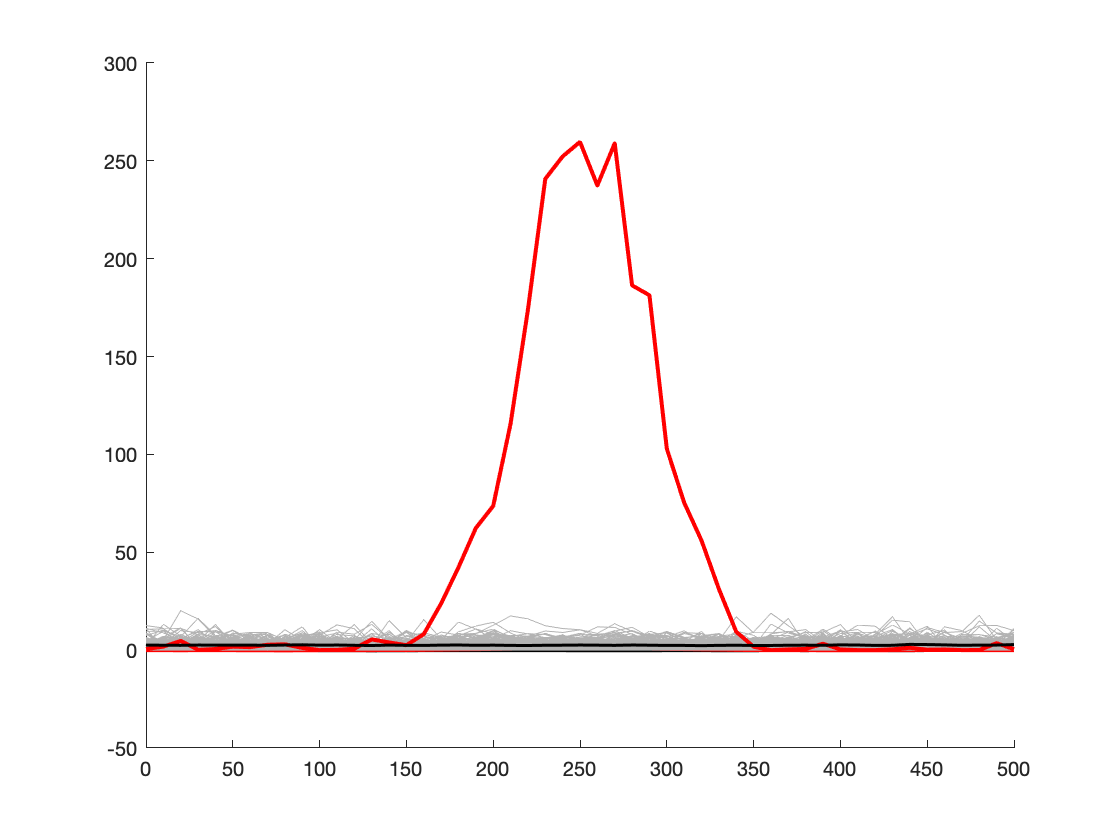

%% Permutation test

% [~, ~, ~, ~, ~, tval, ~] = limo_ttest(2, cond1, cond2, ath);
tval = limo_ttest_light(2, cond1, cond2);
t2 = tval.^2;

% get permutation estimates
t2_perm = zeros(Nf,Nperm);
erpall = cat(2,cond1,cond2);
pval_perm = zeros(Nf,1);

for perm_iter = 1:Nperm
    
    perm_trials = randperm(Nt + Nt);
    perm_cond1 = erpall(:,perm_trials(1:Nt));
    perm_cond2 = erpall(:,perm_trials(Nt+1:Nt+Nt));
    %     [~, ~, ~, ~, ~, tval, ~] = limo_ttest(2,perm_cond1,perm_cond2,ath);
    tval = limo_ttest_light(2,perm_cond1,perm_cond2);
    t2_perm(:,perm_iter) = tval.^2;
    
end
maxt2_perm = max(t2_perm, [], 1);
for F = 1:Nf
    pval_perm(F) = (sum(t2_perm(F,:) > t2(F)) + 1) / (Nperm + 1);
end

% graphical check
plot(Xf, t2_perm, 'Color', [.7 .7 .7])
hold on
plot(Xf, t2, 'r', 'LineWidth', 2)
plot(Xf, prctile(t2_perm, 89, 2), 'k', 'LineWidth', 1.5)

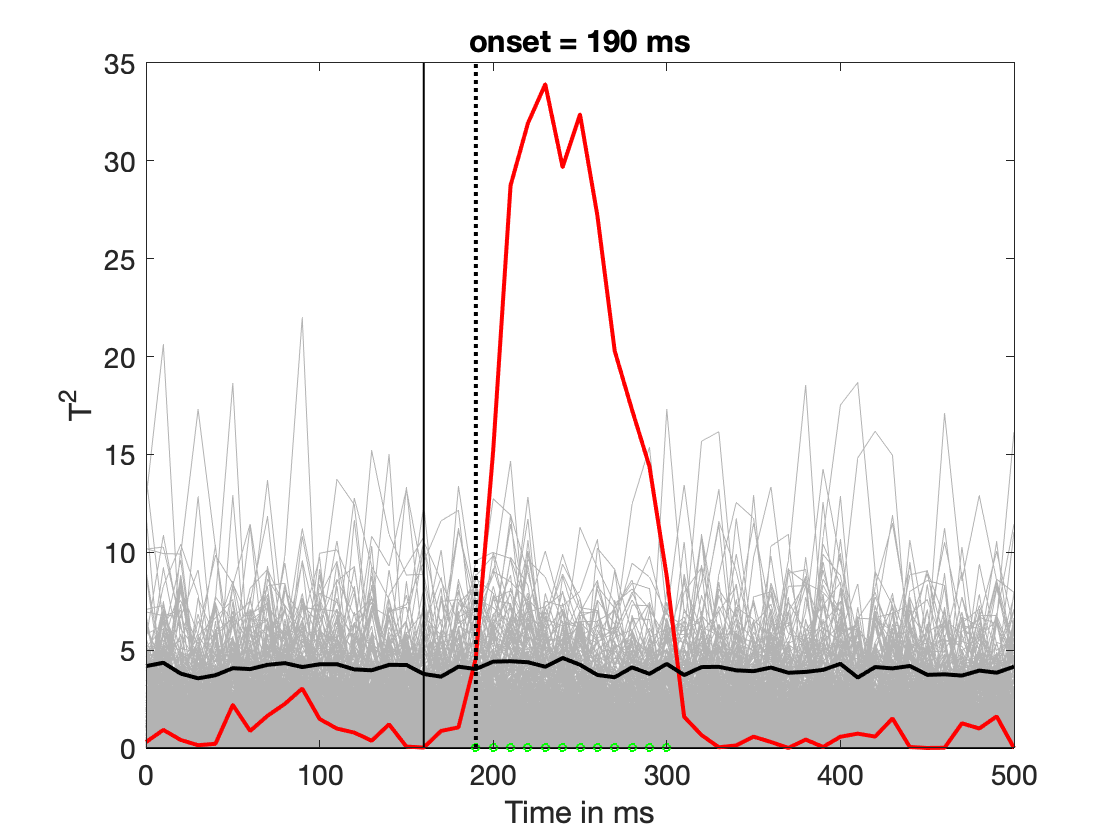

%% CLUSTER onset estimate

% get threshold
perm_th = prctile(t2_perm, pth*100, 2); % univariate thresholds
% because there is no p value for max t^2,
% we use the univariate permutation distributions to threshold themselves
% fake p values: 0 if above threshold, 1 otherwise
pval = t2_perm < repmat(perm_th, 1, Nperm);
% threshold permutation distribution
tmp = t2_perm;
th = limo_ecluster_make(tmp, pval, ath);
% threshold T2 results
sigcluster = limo_ecluster_test(t2, t2 < perm_th, th, ath);
% find onset
onset = find_onset(sigcluster.elec_mask, Xf, 1);

% graphical check
figname = 'fto sim: T2 CLUSTER onset estimate';
figure('Name', figname,'NumberTitle','off','Color','white');
plot(Xf, t2_perm, 'Color', [.7 .7 .7])
hold on
plot(Xf, zeros(Nf,1), 'k', 'LineWidth', 1) % zero reference line
plot(Xf, t2, 'r', 'LineWidth', 2)
plot(Xf, perm_th, 'k', 'LineWidth', 2)
v = axis;
plot(Xf, 2000.*(sigcluster.elec_mask - 1), 'go', 'MarkerSize', 4)
plot([onset onset], [v(3) v(4)], 'k:', 'LineWidth', 2)
plot([true_onset true_onset], [v(3) v(4)], 'k', 'LineWidth', 1)
set(gca, 'Layer', 'top')
ylim([v(3) v(4)])
xlim([0 500])
title(['onset = ',num2str(round(onset)),' ms'])
xlabel('Time in ms')
ylabel('T^2')
ax = gca;
ax.FontSize = 14;

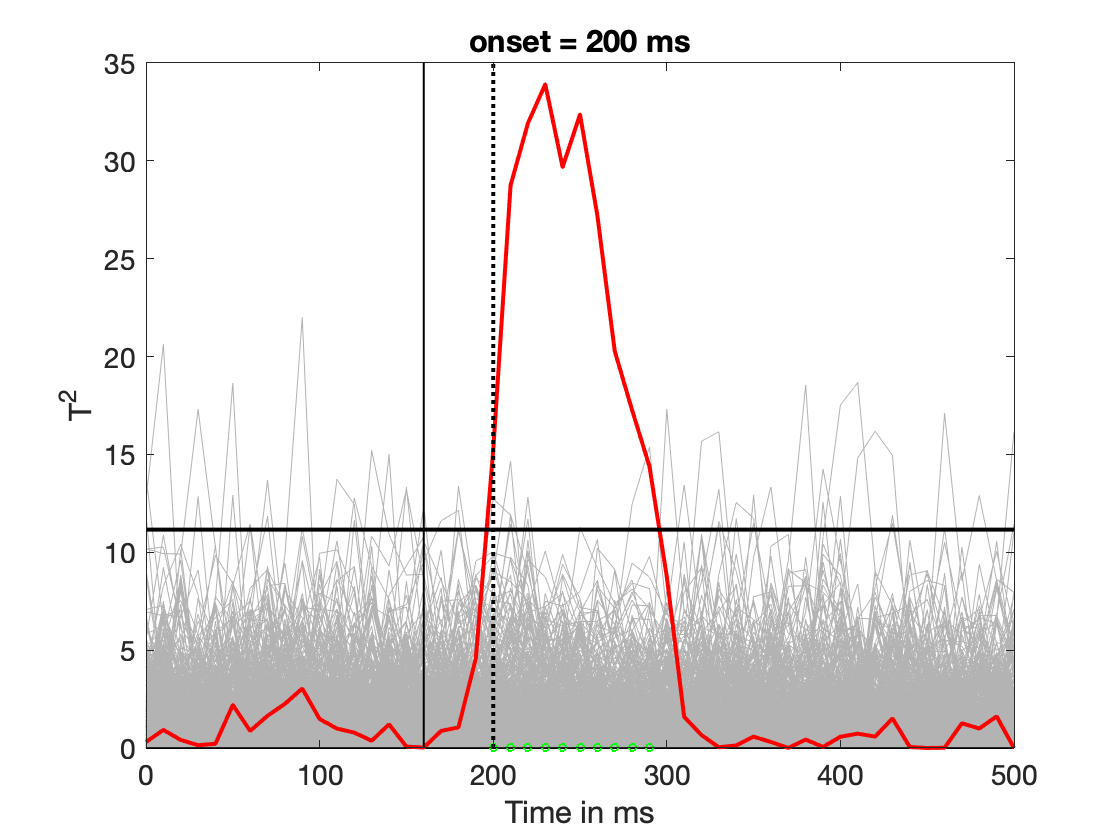

%% MAX onset estimate

max_perm_th = prctile(maxt2_perm, pth*100); % MAX stat threshold
onset = find_onset(t2 > max_perm_th, Xf, 1);

% graphical check
figname = 'fto sim: T2 MAX onset estimate';
figure('Name', figname,'NumberTitle','off','Color','white');
plot(Xf, t2_perm, 'Color', [.7 .7 .7])
hold on
plot(Xf, zeros(Nf,1), 'k', 'LineWidth', 1) % zero reference line
plot(Xf, t2, 'r', 'LineWidth', 2)
plot([0 500], [max_perm_th max_perm_th], 'k', 'LineWidth', 2)
v = axis;
plot(Xf, 2000.*((t2 > max_perm_th) - 1), 'go', 'MarkerSize', 4)
plot([onset onset], [v(3) v(4)], 'k:', 'LineWidth', 2)
plot([true_onset true_onset], [v(3) v(4)], 'k', 'LineWidth', 1)
set(gca, 'Layer', 'top')
ylim([v(3) v(4)])
xlim([0 500])
title(['onset = ',num2str(round(onset)),' ms'])
xlabel('Time in ms')
ylabel('T^2')
ax = gca;
ax.FontSize = 14;

%% FDR onset estimate

pID = limo_FDR(pval_perm, ath);
onset = find_onset(pval_perm < pID, Xf, 1);

% graphical check
figname = 'fto sim: T2 FDR onset estimate';
figure('Name', figname,'NumberTitle','off','Color','white');
plot(Xf, t2_perm, 'Color', [.7 .7 .7])
hold on
plot(Xf, zeros(Nf,1), 'k', 'LineWidth', 1) % zero reference line
plot(Xf, t2, 'r', 'LineWidth', 2)
plot(Xf, perm_th, 'k', 'LineWidth', 2)
v = axis;
plot(Xf, 2000.*((pval_perm < pID) - 1), 'go', 'MarkerSize', 4)
plot([onset onset], [v(3) v(4)], 'k:', 'LineWidth', 2)
plot([true_onset true_onset], [v(3) v(4)], 'k', 'LineWidth', 1)
set(gca, 'Layer', 'top')
ylim([v(3) v(4)])
xlim([0 500])
title(['onset = ',num2str(round(onset)),' ms'])
xlabel('Time in ms')
ylabel('T^2')
ax = gca;
ax.FontSize = 14;


%% ---------------------------------------------------------
%% Simulation: true positives, t^2, Nt=50, var=1, gamma=0.7

% rng(666) % set random seed
% 
% Nsim = 10000;
% Nperm = 1000;
% 
% Nt = 50; % sample size per condition
% outvar = 1; % single-trial noise variance
% gamma = 0.7; % 0 = white noise, 1 = pink noise
% 
% onset_cluster = zeros(1, Nsim);
% onset_max = zeros(1, Nsim);
% onset_fdr = zeros(1, Nsim);
% cohend = zeros(1, Nsim);
% 
% for iter = 1:Nsim
%     
%     if rem(iter,100) == 0
%         disp(['fto sim tp t^2, Nt=50, var=1, gamma=0.7: ',num2str(iter),' / ',num2str(Nsim)])
%     end
%     
%     % template + noise -- max sample size
%     cond1 = zeros(Nf, Nt);
%     cond2 = zeros(Nf, Nt);
%     
%     for T = 1:Nt
%         cond1(:,T) = temp1 + one_over_f(gamma,Nf,outvar)';
%         cond2(:,T) = temp2 + one_over_f(gamma,Nf,outvar)';
%     end
%     
%     % save max Cohen'd
%     allcohen = (mean(cond2, 2) - mean(cond1, 2)) ./ sqrt((var(cond1,0,2) + var(cond2,0,2)) / 2);
%     cohend(iter) = mean(allcohen(25:27));
%     
%     % t-test
%     tval = limo_ttest_light(2, cond1, cond2);
%     t2 = tval.^2;
%     
%     % get permutation estimates
%     t2_perm = zeros(Nf,Nperm);
%     erpall = cat(2,cond1,cond2);
%     
%     for perm_iter = 1:Nperm
%         
%         perm_trials = randperm(Nt + Nt);
%         perm_cond1 = erpall(:,perm_trials(1:Nt));
%         perm_cond2 = erpall(:,perm_trials(Nt+1:Nt+Nt));
%         tval = limo_ttest_light(2,perm_cond1,perm_cond2);
%         t2_perm(:,perm_iter) = tval.^2;
%         
%     end
%     
%     maxt2_perm = max(t2_perm, [], 1);
%     pval_perm = zeros(Nf,1);
%     for F = 1:Nf
%         pval_perm(F) = (sum(t2_perm(F,:) > t2(F)) + 1) / (Nperm + 1);
%     end
%     
%     % CLUSTER onset estimate
%     
%     % get threshold
%     perm_th = prctile(t2_perm, pth*100, 2); % univariate thresholds
%     % because there is no p value for max t^2,
%     % we use the univariate permutation distributions to threshold themselves
%     % fake p values: 0 if above threshold, 1 otherwise
%     pval = t2_perm < repmat(perm_th, 1, Nperm);
%     % threshold permutation distribution
%     tmp = t2_perm;
%     th = limo_ecluster_make(tmp, pval, ath);
%     % threshold T2 results
%     sigcluster = limo_ecluster_test(t2, t2 < perm_th, th, ath);
%     % find onset
%     try
%         onset_cluster(iter) = find_onset(sigcluster.elec_mask, Xf, 0);
%     catch
%         onset_cluster(iter) = NaN;
%     end
%     
%     % MAX onset estimate
%     max_perm_th = prctile(maxt2_perm, pth*100); % MAX stat threshold
%     try
%         onset_max(iter) = find_onset(t2 > max_perm_th, Xf, 0);
%     catch
%         onset_max(iter) = NaN;
%     end
%     
%     % FDR onset estimate
%     [pID,pN] = FDR(pval_perm, ath);
%     try
%         onset_fdr(iter) = find_onset(pval_perm < pID, Xf, 0);
%     catch
%         onset_fdr(iter) = NaN;
%     end
%     
% end

fto sim tp t^2, Nt=50, var=1, gamma=0.7: 100 / 10000
fto sim tp t^2, Nt=50, var=1, gamma=0.7: 200 / 10000


% 
% save([corepath,'/fto_sim_tp_t2_n50_var1_gamma07'], ...
%     'onset_cluster', 'onset_max', 'onset_fdr', 'cohend', ...
%     'Nsim', 'Nperm')


%% Simulation results: true positives, t^2 -- one gamma/outvar/Nt
% Check results for one combination of variables.

true_onset = 160;
load([corepath,'/fto_sim_tp_t2_n50_var1_gamma07'])

% remove NaN
oc = onset_cluster;
oc = oc(~isnan(oc));
om = onset_max;
om = om(~isnan(om));
of = onset_fdr;
of = of(~isnan(of));
coh = cohend;
coh = coh(~isnan(coh));

% check true positives
tpc = length(oc) / Nsim;
tpm = length(om) / Nsim;
tpf = length(of) / Nsim;

% median onsets
mdo_c = median(oc);
mdo_m = median(om);
mdo_f = median(of);
mdo = [mdo_c mdo_m mdo_f];

disp('-----------------------------------------------------')

-----------------------------------------------------


disp('True positives:')

True positives:


disp(['cluster = ',num2str(round(tpc*100,1)),' %'])

cluster = 100 %


disp(['max = ',num2str(round(tpm*100,1)),' %'])

max = 99.9 %


disp(['fdr  = ',num2str(round(tpf*100,1)),' %'])

fdr  = 96.6 %


disp('-----------------------------------------------------')

-----------------------------------------------------


disp('Max Cohen d:')

Max Cohen d:


disp(['min = ',num2str(round(min(coh),1))])

min = 0.3


disp(['max = ',num2str(round(max(coh),1))])

max = 1.8


disp(['median  = ',num2str(round(median(coh),1))])

median  = 1


disp('-----------------------------------------------------')

-----------------------------------------------------


disp('Median onsets:')

Median onsets:


disp(['cluster = ',num2str(round(mdo_c)),' ms'])

cluster = 190 ms


disp(['max = ',num2str(round(mdo_m)),' ms'])

max = 200 ms


disp(['fdr = ',num2str(round(mdo_f)),' ms'])

fdr = 200 ms


disp('-----------------------------------------------------')

-----------------------------------------------------


disp('Mean absolute error (MAE):')

Mean absolute error (MAE):


disp(['cluster = ',num2str(round(mean(abs(oc-true_onset)))),' ms'])

cluster = 29 ms


disp(['max = ',num2str(round(mean(abs(om-true_onset)))),' ms'])

max = 46 ms


disp(['fdr = ',num2str(round(mean(abs(of-true_onset)))),' ms'])

fdr = 43 ms


disp('-----------------------------------------------------')

-----------------------------------------------------


disp('Bias:')

Bias:


disp(['cluster = ',num2str(round(median(oc)-true_onset)),' ms'])

cluster = 30 ms


disp(['max = ',num2str(round(median(om)-true_onset)),' ms'])

max = 40 ms


disp(['fdr = ',num2str(round(median(of)-true_onset)),' ms'])

fdr = 40 ms


disp('-----------------------------------------------------')

-----------------------------------------------------


disp('Underestimations of at least 40 ms:')

Underestimations of at least 40 ms:


disp(['cluster = ',num2str(round(100*mean((oc-true_onset)<= -40),1)),' %'])

cluster = 1.5 %


disp(['max = ',num2str(round(100*mean((om-true_onset)<= -40),1)),' %'])

max = 1.3 %


disp(['fdr = ',num2str(round(100*mean((of-true_onset)<= -40),1)),' %'])

fdr = 7.7 %


disp('-----------------------------------------------------')

-----------------------------------------------------


disp('Proportion too early:')

Proportion too early:


disp(['cluster = ',num2str(round(100*mean((oc-true_onset)< 0),1)),' %'])

cluster = 2.8 %


disp(['max = ',num2str(round(100*mean((om-true_onset)< 0),1)),' %'])

max = 1.7 %


disp(['fdr = ',num2str(round(100*mean((of-true_onset)< 0),1)),' %'])

fdr = 9.1 %


disp('-----------------------------------------------------')

-----------------------------------------------------


disp('Variance:')

Variance:


disp(['cluster = ',num2str(round(var(oc,1))),' ms'])

cluster = 507 ms


disp(['max = ',num2str(round(var(om,1))),' ms'])

max = 568 ms


disp(['fdr = ',num2str(round(var(of,1))),' ms'])

fdr = 1816 ms


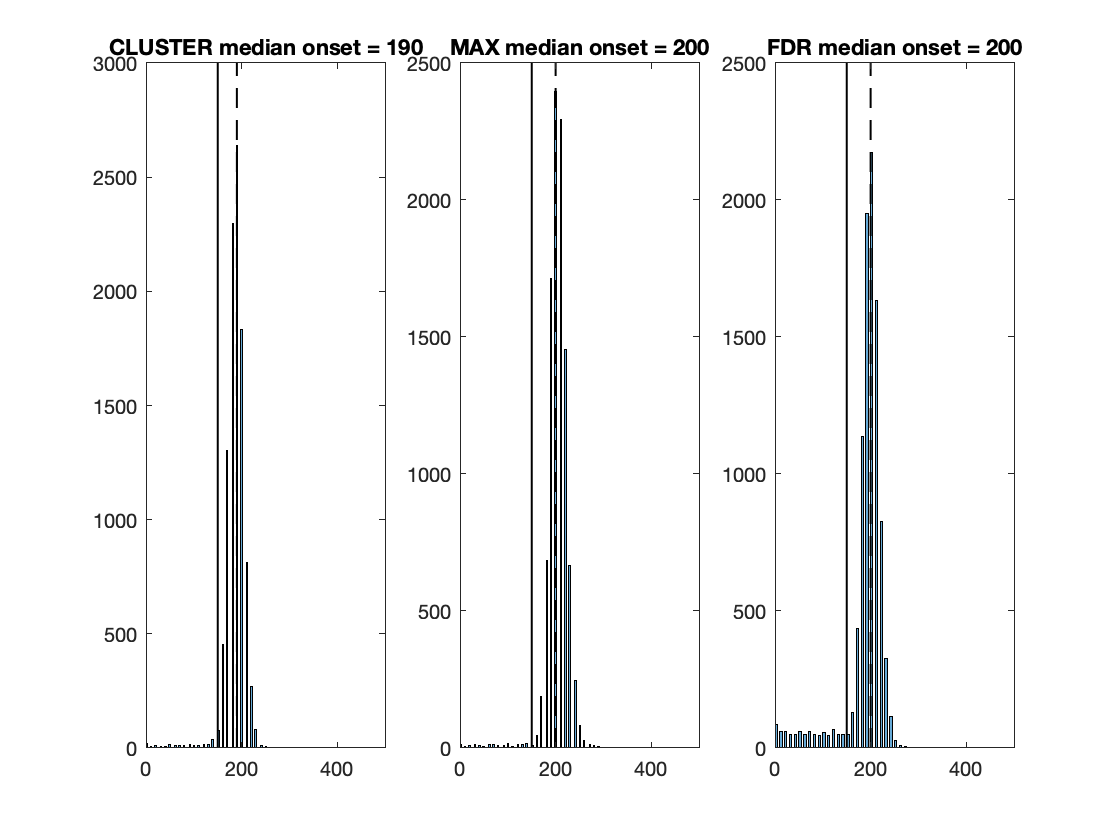



figure('NumberTitle','off', 'Name', ['nt=',num2str(Nt),', var=',num2str(outvar),', gamma=',num2str(gamma)])

subplot(1,3,1)
histogram(oc, 'Normalization', 'count')
title(['CLUSTER median onset = ',num2str(round(mdo_c))])

subplot(1,3,2)
histogram(om, 'Normalization', 'count')
title(['MAX median onset = ',num2str(round(mdo_m))])

subplot(1,3,3)
histogram(of, 'Normalization', 'count')
title(['FDR median onset = ',num2str(round(mdo_f))])

for sub = 1:3
    subplot(1,3,sub)
    hold on
    xlim([0 500])
    v = axis;
    plot([150 150], [v(3) v(4)], 'k', 'LineWidth', 1)
    plot([mdo(sub) mdo(sub)], [v(3) v(4)], 'k--', 'LineWidth', 1)
end

%% ---------------------------------------------------------
%% Simulation: true positives, t^2, n=50, sd=1, vary gamma -- redo with bivariate MI

% rng(666) % set random seed
% 
% Nsim = 10000;
% Nperm = 1000;
% 
% Nt = 50;
% outvar = 1;
% 
% gamma_vec = 0:0.1:1; % 0 = white noise, 1 = pink noise
% gamma_length = length(gamma_vec);
% 
% onset_cluster = zeros(gamma_length, Nsim);
% onset_max = zeros(gamma_length, Nsim);
% onset_fdr = zeros(gamma_length, Nsim);
% cohend = zeros(gamma_length, Nsim);
% 
% for iter = 1:Nsim
%     
%     if rem(iter,100) == 0
%         disp(['fto sim tp t^2 vary gamma: ',num2str(iter),' / ',num2str(Nsim)])
%     end
%     
%     for iter_gamma = 1:gamma_length
%         
%         gamma = gamma_vec(iter_gamma);
%         
%         % template + noise -- max sample size
%         cond1 = zeros(Nf, Nt);
%         cond2 = zeros(Nf, Nt);
%         
%         for T = 1:Nt
%             cond1(:,T) = temp1 + one_over_f(gamma,Nf,outvar)';
%             cond2(:,T) = temp2 + one_over_f(gamma,Nf,outvar)';
%         end
%         
%         % save max Cohen'd
%         allcohen = (mean(cond2, 2) - mean(cond1, 2)) ./ sqrt((var(cond1,0,2) + var(cond2,0,2)) / 2);
%         cohend(iter_gamma, iter) = mean(allcohen(25:27));
%         
%         % t-test
%         tval = limo_ttest_light(2, cond1, cond2);
%         t2 = tval.^2;
%         
%         % get permutation estimates
%         t2_perm = zeros(Nf,Nperm);
%         erpall = cat(2,cond1,cond2);
%         
%         for perm_iter = 1:Nperm
%             
%             perm_trials = randperm(Nt + Nt);
%             perm_cond1 = erpall(:,perm_trials(1:Nt));
%             perm_cond2 = erpall(:,perm_trials(Nt+1:Nt+Nt));
%             tval = limo_ttest_light(2,perm_cond1,perm_cond2);
%             t2_perm(:,perm_iter) = tval.^2;
%             
%         end
%         
%         maxt2_perm = max(t2_perm, [], 1);
%         pval_perm = zeros(Nf,1);
%         for F = 1:Nf
%             pval_perm(F) = (sum(t2_perm(F,:) > t2(F)) + 1) / (Nperm + 1);
%         end
%         
%         % CLUSTER onset estimate
%         
%         % get threshold
%         perm_th = prctile(t2_perm, pth*100, 2); % univariate thresholds
%         % because there is no p value for max t^2,
%         % we use the univariate permutation distributions to threshold themselves
%         % fake p values: 0 if above threshold, 1 otherwise
%         pval = t2_perm < repmat(perm_th, 1, Nperm);
%         % threshold permutation distribution
%         tmp = t2_perm;
%         th = limo_ecluster_make(tmp, pval, ath);
%         % threshold T2 results
%         sigcluster = limo_ecluster_test(t2, t2 < perm_th, th, ath);
%         % find onset
%         try
%             onset_cluster(iter_gamma, iter) = find_onset(sigcluster.elec_mask, Xf, 0);
%         catch
%             onset_cluster(iter_gamma, iter) = NaN;
%         end
%         
%         % MAX onset estimate
%         max_perm_th = prctile(maxt2_perm, pth*100); % MAX stat threshold
%         try
%             onset_max(iter_gamma, iter) = find_onset(t2 > max_perm_th, Xf, 0);
%         catch
%             onset_max(iter_gamma, iter) = NaN;
%         end
%         
%         % FDR onset estimate
%         [pID,pN] = FDR(pval_perm, ath);
%         try
%             onset_fdr(iter_gamma, iter) = find_onset(pval_perm < pID, Xf, 0);
%         catch
%             onset_fdr(iter_gamma, iter) = NaN;
%         end
%         
%     end % gamma loop
%     
% end
% 
% save([corepath,'/fto_sim_tp_t2_n50_var1_gammavar'], ...
%     'onset_cluster', 'onset_max', 'onset_fdr', 'cohend', ...
%     'Nsim', 'Nperm', 'gamma_vec')


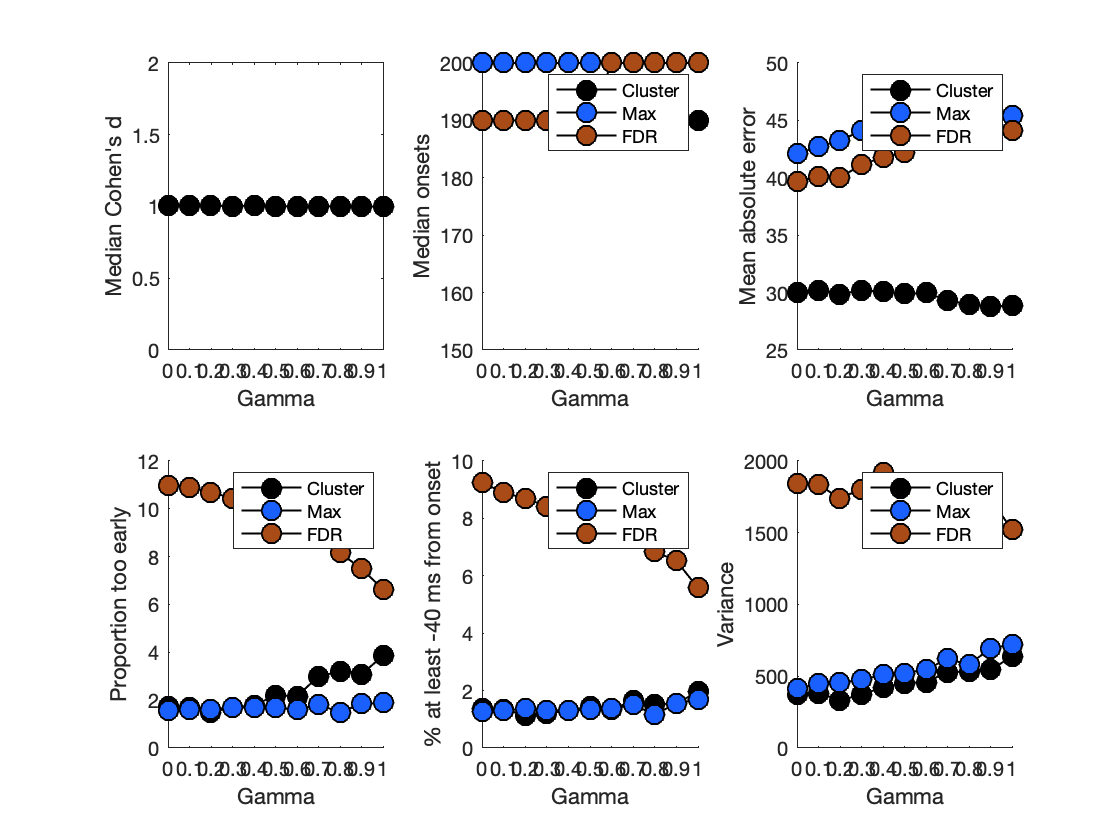

%% Simulation results: true positives, t^2, n=50, sd=1, vary gamma
% Check results for one combination of variables.

true_onset = 160;
load([corepath,'/fto_sim_tp_t2_n50_var1_gammavar'])
Ng = length(gamma_vec);
% compute performance statistics

mdcoh = zeros(1,Ng);
mdo = zeros(3,Ng);
mae = zeros(3,Ng);
bias = zeros(3,Ng);
u40 = zeros(3,Ng);
u0 = zeros(3,Ng);
distvar = zeros(3,Ng);

for G = 1:Ng
    
    % remove NaN
    oc = squeeze(onset_cluster(G,:));
    oc = oc(~isnan(oc));
    om = squeeze(onset_max(G,:));
    om = om(~isnan(om));
    of = squeeze(onset_fdr(G,:));
    of = of(~isnan(of));
    coh = squeeze(cohend(G,:));
    coh = coh(~isnan(coh));
    
    mdcoh(G) = median(coh); % median Cohen's d
    
    % median onsets
    mdo(1,G) = median(oc); % cluster
    mdo(2,G) = median(om); % max
    mdo(3,G) = median(of); % FDR
    
    % Mean absolute error (MAE)
    mae(1,G) = mean(abs(oc-true_onset)); % cluster
    mae(2,G) = mean(abs(om-true_onset)); % max
    mae(3,G) = mean(abs(of-true_onset)); % FDR
    
    % Bias
    bias(1,G) = median(oc)-true_onset; % cluster
    bias(2,G) = median(om)-true_onset; % max
    bias(3,G) = median(of)-true_onset; % FDR
    
    % Underestimations of at least 40 ms
    u40(1,G) = 100*mean((oc-true_onset) <= -40); % cluster
    u40(2,G) = 100*mean((om-true_onset) <= -40); % max
    u40(3,G) = 100*mean((of-true_onset) <= -40); % FDR
    
    % Proportion too early
    u0(1,G) = 100*mean((oc-true_onset) < 0); % cluster
    u0(2,G) = 100*mean((om-true_onset) < 0); % max
    u0(3,G) = 100*mean((of-true_onset) < 0); % FDR
    
    % Variance
    distvar(1,G) = var(oc); % cluster
    distvar(2,G) = var(om); % max
    distvar(3,G) = var(of); % FDR
    
end

figure('NumberTitle','off', 'Name', 'nt=50, var=1, vary gamma')

subplot(2,3,1) % Cohen's d 
plot(gamma_vec, mdcoh, '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0]) % MarkerEdgeColor
xticks(gamma_vec)
xlabel('Gamma')
ylabel('Median Cohen''s d')
ylim([0 2])

subplot(2,3,2) % Median onsets
hold on
plot(gamma_vec, mdo(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(gamma_vec, mdo(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(gamma_vec, mdo(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(gamma_vec)
xlabel('Gamma')
ylabel('Median onsets')
ylim([150 200])
legend('Cluster', 'Max', 'FDR')

subplot(2,3,3) % Mean absolute error
hold on
plot(gamma_vec, mae(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(gamma_vec, mae(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(gamma_vec, mae(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(gamma_vec)
xlabel('Gamma')
ylabel('Mean absolute error')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,4) % Proportion too early (u0)
hold on
plot(gamma_vec, u0(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(gamma_vec, u0(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(gamma_vec, u0(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(gamma_vec)
xlabel('Gamma')
ylabel('Proportion too early')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,5) % Underestimations of at least 40 ms (u40)
hold on
plot(gamma_vec, u40(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(gamma_vec, u40(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(gamma_vec, u40(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(gamma_vec)
xlabel('Gamma')
ylabel('% at least -40 ms from onset')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,6) % Variance (distvar)
hold on
plot(gamma_vec, distvar(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(gamma_vec, distvar(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(gamma_vec, distvar(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(gamma_vec)
xlabel('Gamma')
ylabel('Variance')
legend('Cluster', 'Max', 'FDR')

%% ---------------------------------------------------------
%% Simulation: true positives, t^2, vary n, var=1, gamma=0.7 -- redo with bivariate MI

% rng(666) % set random seed
% 
% Nsim = 10000;
% Nperm = 1000;
% 
% n_vec = 20:10:150; % sample size per condition
% n_length = length(n_vec);
% n_max = max(n_vec);
% 
% outvar = 1; % single-trial noise variance
% gamma = 0.7; % 0 = white noise, 1 = pink noise
% 
% onset_cluster = zeros(n_length, Nsim);
% onset_max = zeros(n_length, Nsim);
% onset_fdr = zeros(n_length, Nsim);
% cohend = zeros(n_length, Nsim);
% 
% for iter = 1:Nsim
%     
%     if rem(iter,100) == 0
%         disp(['fto sim tp t^2 vary n: ',num2str(iter),' / ',num2str(Nsim)])
%     end
%     
%     % template + noise -- max sample size
%     cond1_all = zeros(Nf, n_max);
%     cond2_all = zeros(Nf, n_max);
%     
%     for T = 1:n_max
%         cond1_all(:,T) = temp1 + one_over_f(gamma,Nf,outvar)';
%         cond2_all(:,T) = temp2 + one_over_f(gamma,Nf,outvar)';
%     end
%     
%     for iter_n = 1:n_length
%         
%         % downsample to current size
%         Nt = n_vec(iter_n);
%         cond1 = cond1_all(:,1:Nt);
%         cond2 = cond2_all(:,1:Nt);
%         
%         % save max Cohen'd
%         allcohen = (mean(cond2, 2) - mean(cond1, 2)) ./ sqrt((var(cond1,0,2) + var(cond2,0,2)) / 2);
%         cohend(iter_n, iter) = mean(allcohen(25:27));
%         
%         % t-test
%         tval = limo_ttest_light(2, cond1, cond2);
%         t2 = tval.^2;
%         
%         % get permutation estimates
%         t2_perm = zeros(Nf,Nperm);
%         erpall = cat(2,cond1,cond2);
%         
%         for perm_iter = 1:Nperm
%             
%             perm_trials = randperm(Nt + Nt);
%             perm_cond1 = erpall(:,perm_trials(1:Nt));
%             perm_cond2 = erpall(:,perm_trials(Nt+1:Nt+Nt));
%             tval = limo_ttest_light(2,perm_cond1,perm_cond2);
%             t2_perm(:,perm_iter) = tval.^2;
%             
%         end
%         
%         maxt2_perm = max(t2_perm, [], 1);
%         pval_perm = zeros(Nf,1);
%         for F = 1:Nf
%             pval_perm(F) = (sum(t2_perm(F,:) > t2(F)) + 1) / (Nperm + 1);
%         end
%         
%         % CLUSTER onset estimate
%         
%         % get threshold
%         perm_th = prctile(t2_perm, pth*100, 2); % univariate thresholds
%         % because there is no p value for max t^2,
%         % we use the univariate permutation distributions to threshold themselves
%         % fake p values: 0 if above threshold, 1 otherwise
%         pval = t2_perm < repmat(perm_th, 1, Nperm);
%         % threshold permutation distribution
%         tmp = t2_perm;
%         th = limo_ecluster_make(tmp, pval, ath);
%         % threshold T2 results
%         sigcluster = limo_ecluster_test(t2, t2 < perm_th, th, ath);
%         % find onset
%         try
%             onset_cluster(iter_n, iter) = find_onset(sigcluster.elec_mask, Xf, 0);
%         catch
%             onset_cluster(iter_n, iter) = NaN;
%         end
%         
%         % MAX onset estimate
%         max_perm_th = prctile(maxt2_perm, pth*100); % MAX stat threshold
%         try
%             onset_max(iter_n, iter) = find_onset(t2 > max_perm_th, Xf, 0);
%         catch
%             onset_max(iter_n, iter) = NaN;
%         end
%         
%         % FDR onset estimate
%         [pID,pN] = FDR(pval_perm, ath);
%         try
%             onset_fdr(iter_n, iter) = find_onset(pval_perm < pID, Xf, 0);
%         catch
%             onset_fdr(iter_n, iter) = NaN;
%         end
%         
%     end % size loop
%     
% end
% 
% save([corepath,'/fto_sim_tp_t2_nvar_var1_gamma07'], ...
%     'onset_cluster', 'onset_max', 'onset_fdr', 'cohend', ...
%     'Nsim', 'Nperm', 'n_vec')


%% Simulation results: true positives, t^2, vary n, var=1, gamma=0.7
% Check results for one combination of variables.

true_onset = 160;
load([corepath,'/fto_sim_tp_t2_nvar_var1_gamma07'])
Ng = length(n_vec);
% compute performance statistics

mdcoh = zeros(1,Ng);
mdo = zeros(3,Ng);
mae = zeros(3,Ng);
bias = zeros(3,Ng);
u40 = zeros(3,Ng);
u0 = zeros(3,Ng);
distvar = zeros(3,Ng);

for G = 1:Ng
    
    % remove NaN
    oc = squeeze(onset_cluster(G,:));
    oc = oc(~isnan(oc));
    om = squeeze(onset_max(G,:));
    om = om(~isnan(om));
    of = squeeze(onset_fdr(G,:));
    of = of(~isnan(of));
    coh = squeeze(cohend(G,:));
    coh = coh(~isnan(coh));
    
    mdcoh(G) = median(coh); % median Cohen's d
    
    % median onsets
    mdo(1,G) = median(oc); % cluster
    mdo(2,G) = median(om); % max
    mdo(3,G) = median(of); % FDR
    
    % Mean absolute error (MAE)
    mae(1,G) = mean(abs(oc-true_onset)); % cluster
    mae(2,G) = mean(abs(om-true_onset)); % max
    mae(3,G) = mean(abs(of-true_onset)); % FDR
    
    % Proportion too early
    u0(1,G) = 100*mean((oc-true_onset) < 0); % cluster
    u0(2,G) = 100*mean((om-true_onset) < 0); % max
    u0(3,G) = 100*mean((of-true_onset) < 0); % FDR
    
    % Underestimations of at least 40 ms
    u40(1,G) = 100*mean((oc-true_onset) <= -40); % cluster
    u40(2,G) = 100*mean((om-true_onset) <= -40); % max
    u40(3,G) = 100*mean((of-true_onset) <= -40); % FDR
    
    % Variance
    distvar(1,G) = var(oc); % cluster
    distvar(2,G) = var(om); % max
    distvar(3,G) = var(of); % FDR
    
end

figure('NumberTitle','off', 'Name', 'vary n, var=1, gamma=0.7')

subplot(2,3,1) % Cohen's d 
plot(n_vec, mdcoh, '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0]) % MarkerEdgeColor
xticks(n_vec)
xlabel('Sample size')
ylabel('Median Cohen''s d')
ylim([0 2])

subplot(2,3,2) % Median onsets
hold on
plot(n_vec, mdo(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(n_vec, mdo(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(n_vec, mdo(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(n_vec)
xlabel('Sample size')
ylabel('Median onsets')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,3) % Mean absolute error
hold on
plot(n_vec, mae(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(n_vec, mae(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(n_vec, mae(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(n_vec)
xlabel('Sample size')
ylabel('Mean absolute error')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,4) % Proportion too early
hold on
plot(n_vec, u0(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(n_vec, u0(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(n_vec, u0(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(n_vec)
xlabel('Sample size')
ylabel('Proportion too early')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,5) % Underestimations of at least 40 ms (u40)
hold on
plot(n_vec, u40(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(n_vec, u40(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(n_vec, u40(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(n_vec)
xlabel('Sample size')
ylabel('% at least -40 ms from onset')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,6) % Variance (distvar)
hold on
plot(n_vec, distvar(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(n_vec, distvar(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(n_vec, distvar(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(n_vec)
xlabel('Sample size')
ylabel('Variance')
legend('Cluster', 'Max', 'FDR')


%% ---------------------------------------------------------
%% Simulation: true positives, t^2, n=50, vary var, gamma=0.7 -- redo with bivariate MI

% rng(666) % set random seed
% 
% Nsim = 10000;
% Nperm = 1000;
% 
% Nt = 50;
% 
% var_vec = [0.1 0.5:0.5:3]; % single-trial noise variance
% var_length = length(var_vec);
% 
% gamma = 0.7; % 0 = white noise, 1 = pink noise
% 
% onset_cluster = zeros(var_length, Nsim);
% onset_max = zeros(var_length, Nsim);
% onset_fdr = zeros(var_length, Nsim);
% cohend = zeros(var_length, Nsim);
% 
% for iter = 1:Nsim
%     
%     if rem(iter,100) == 0
%         disp(['fto sim tp t^2 vary noise var: ',num2str(iter),' / ',num2str(Nsim)])
%     end
%     
%     for iter_var = 1:var_length
%         
%         outvar = var_vec(iter_var);
%         
%         % template + noise -- max sample size
%         cond1 = zeros(Nf, Nt);
%         cond2 = zeros(Nf, Nt);
%         
%         for T = 1:Nt
%             cond1(:,T) = temp1 + one_over_f(gamma,Nf,outvar)';
%             cond2(:,T) = temp2 + one_over_f(gamma,Nf,outvar)';
%         end
%         
%         % save max Cohen'd
%         allcohen = (mean(cond2, 2) - mean(cond1, 2)) ./ sqrt((var(cond1,0,2) + var(cond2,0,2)) / 2);
%         cohend(iter_var, iter) = mean(allcohen(25:27));
%         
%         % t-test
%         tval = limo_ttest_light(2, cond1, cond2);
%         t2 = tval.^2;
%         
%         % get permutation estimates
%         t2_perm = zeros(Nf,Nperm);
%         erpall = cat(2,cond1,cond2);
%         
%         for perm_iter = 1:Nperm
%             
%             perm_trials = randperm(Nt + Nt);
%             perm_cond1 = erpall(:,perm_trials(1:Nt));
%             perm_cond2 = erpall(:,perm_trials(Nt+1:Nt+Nt));
%             tval = limo_ttest_light(2,perm_cond1,perm_cond2);
%             t2_perm(:,perm_iter) = tval.^2;
%             
%         end
%         
%         maxt2_perm = max(t2_perm, [], 1);
%         pval_perm = zeros(Nf,1);
%         for F = 1:Nf
%             pval_perm(F) = (sum(t2_perm(F,:) > t2(F)) + 1) / (Nperm + 1);
%         end
%         
%         % CLUSTER onset estimate
%         
%         % get threshold
%         perm_th = prctile(t2_perm, pth*100, 2); % univariate thresholds
%         % because there is no p value for max t^2,
%         % we use the univariate permutation distributions to threshold themselves
%         % fake p values: 0 if above threshold, 1 otherwise
%         pval = t2_perm < repmat(perm_th, 1, Nperm);
%         % threshold permutation distribution
%         tmp = t2_perm;
%         th = limo_ecluster_make(tmp, pval, ath);
%         % threshold T2 results
%         sigcluster = limo_ecluster_test(t2, t2 < perm_th, th, ath);
%         % find onset
%         try
%             onset_cluster(iter_var, iter) = find_onset(sigcluster.elec_mask, Xf, 0);
%         catch
%             onset_cluster(iter_var, iter) = NaN;
%         end
%         
%         % MAX onset estimate
%         max_perm_th = prctile(maxt2_perm, pth*100); % MAX stat threshold
%         try
%             onset_max(iter_var, iter) = find_onset(t2 > max_perm_th, Xf, 0);
%         catch
%             onset_max(iter_var, iter) = NaN;
%         end
%         
%         % FDR onset estimate
%         [pID,pN] = FDR(pval_perm, ath);
%         try
%             onset_fdr(iter_var, iter) = find_onset(pval_perm < pID, Xf, 0);
%         catch
%             onset_fdr(iter_var, iter) = NaN;
%         end
%         
%     end % noise variance loop
%     
% end
% 
% save([corepath,'/fto_sim_tp_t2_n50_varvar_gamma07'], ...
%     'onset_cluster', 'onset_max', 'onset_fdr', 'cohend', ...
%     'Nsim', 'Nperm', 'var_vec')


%% Simulation results: true positives, t^2, n=50, vary var, gamma=0.7
% Check results for one combination of variables.

true_onset = 160;
load([corepath,'/fto_sim_tp_t2_n50_varvar_gamma07'])
Ng = length(var_vec);
% compute performance statistics

mdcoh = zeros(1,Ng);
mdo = zeros(3,Ng);
mae = zeros(3,Ng);
bias = zeros(3,Ng);
u40 = zeros(3,Ng);
u0 = zeros(3,Ng);
distvar = zeros(3,Ng);

for G = 1:Ng
    
    % remove NaN
    oc = squeeze(onset_cluster(G,:));
    oc = oc(~isnan(oc));
    om = squeeze(onset_max(G,:));
    om = om(~isnan(om));
    of = squeeze(onset_fdr(G,:));
    of = of(~isnan(of));
    coh = squeeze(cohend(G,:));
    coh = coh(~isnan(coh));
    
    mdcoh(G) = median(coh); % median Cohen's d
    
    % median onsets
    mdo(1,G) = median(oc); % cluster
    mdo(2,G) = median(om); % max
    mdo(3,G) = median(of); % FDR
    
    % Mean absolute error (MAE)
    mae(1,G) = mean(abs(oc-true_onset)); % cluster
    mae(2,G) = mean(abs(om-true_onset)); % max
    mae(3,G) = mean(abs(of-true_onset)); % FDR
    
    % Proportion too early
    u0(1,G) = 100*mean((oc-true_onset) < 0); % cluster
    u0(2,G) = 100*mean((om-true_onset) < 0); % max
    u0(3,G) = 100*mean((of-true_onset) < 0); % FDR
    
    % Underestimations of at least 40 ms
    u40(1,G) = 100*mean((oc-true_onset) <= -40); % cluster
    u40(2,G) = 100*mean((om-true_onset) <= -40); % max
    u40(3,G) = 100*mean((of-true_onset) <= -40); % FDR
    
    % Variance
    distvar(1,G) = var(oc); % cluster
    distvar(2,G) = var(om); % max
    distvar(3,G) = var(of); % FDR
    
end

figure('NumberTitle','off', 'Name', 'nt=50, vary var, gamma=0.7')

subplot(2,3,1) % Cohen's d 
plot(var_vec, mdcoh, '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0]) % MarkerEdgeColor
xticks(var_vec)
xlabel('Noise variance')
ylabel('Median Cohen''s d')
ylim([0 2])

subplot(2,3,2) % Median onsets
hold on
plot(var_vec, mdo(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(var_vec, mdo(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(var_vec, mdo(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(var_vec)
xlabel('Noise variance')
ylabel('Median onsets')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,3) % Mean absolute error
hold on
plot(var_vec, mae(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(var_vec, mae(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(var_vec, mae(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(var_vec)
xlabel('Noise variance')
ylabel('Mean absolute error')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,4) % Proportion too early
hold on
plot(var_vec, u0(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(var_vec, u0(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(var_vec, u0(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(var_vec)
xlabel('Noise variance')
ylabel('Bias')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,5) % Underestimations of at least 40 ms (u40)
hold on
plot(var_vec, u40(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(var_vec, u40(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(var_vec, u40(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(var_vec)
xlabel('Noise variance')
ylabel('% at least -40 ms from onset')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,6) % Variance (distvar)
hold on
plot(var_vec, distvar(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(var_vec, distvar(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(var_vec, distvar(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(var_vec)
xlabel('Noise variance')
ylabel('Variance')
legend('Cluster', 'Max', 'FDR')


%% ---------------------------------------------------------
%% Simulation: true positives, t^2, n=100, vary var, gamma=0.7 -- redo with bivariate MI

% rng(666) % set random seed
% 
% Nsim = 10000;
% Nperm = 1000;
% 
% Nt = 100;
% 
% var_vec = [0.1 0.5:0.5:3]; % single-trial noise variance
% var_length = length(var_vec);
% 
% gamma = 0.7; % 0 = white noise, 1 = pink noise
% 
% onset_cluster = zeros(var_length, Nsim);
% onset_max = zeros(var_length, Nsim);
% onset_fdr = zeros(var_length, Nsim);
% cohend = zeros(var_length, Nsim);
% 
% for iter = 1:Nsim
%     
%     if rem(iter,100) == 0
%         disp(['fto sim tp t^2 vary noise var: ',num2str(iter),' / ',num2str(Nsim)])
%     end
%     
%     for iter_var = 1:var_length
%         
%         outvar = var_vec(iter_var);
%         
%         % template + noise -- max sample size
%         cond1 = zeros(Nf, Nt);
%         cond2 = zeros(Nf, Nt);
%         
%         for T = 1:Nt
%             cond1(:,T) = temp1 + one_over_f(gamma,Nf,outvar)';
%             cond2(:,T) = temp2 + one_over_f(gamma,Nf,outvar)';
%         end
%         
%         % save max Cohen'd
%         allcohen = (mean(cond2, 2) - mean(cond1, 2)) ./ sqrt((var(cond1,0,2) + var(cond2,0,2)) / 2);
%         cohend(iter_var, iter) = mean(allcohen(25:27));
%         
%         % t-test
%         tval = limo_ttest_light(2, cond1, cond2);
%         t2 = tval.^2;
%         
%         % get permutation estimates
%         t2_perm = zeros(Nf,Nperm);
%         erpall = cat(2,cond1,cond2);
%         
%         for perm_iter = 1:Nperm
%             
%             perm_trials = randperm(Nt + Nt);
%             perm_cond1 = erpall(:,perm_trials(1:Nt));
%             perm_cond2 = erpall(:,perm_trials(Nt+1:Nt+Nt));
%             tval = limo_ttest_light(2,perm_cond1,perm_cond2);
%             t2_perm(:,perm_iter) = tval.^2;
%             
%         end
%         
%         maxt2_perm = max(t2_perm, [], 1);
%         pval_perm = zeros(Nf,1);
%         for F = 1:Nf
%             pval_perm(F) = (sum(t2_perm(F,:) > t2(F)) + 1) / (Nperm + 1);
%         end
%         
%         % CLUSTER onset estimate
%         
%         % get threshold
%         perm_th = prctile(t2_perm, pth*100, 2); % univariate thresholds
%         % because there is no p value for max t^2,
%         % we use the univariate permutation distributions to threshold themselves
%         % fake p values: 0 if above threshold, 1 otherwise
%         pval = t2_perm < repmat(perm_th, 1, Nperm);
%         % threshold permutation distribution
%         tmp = t2_perm;
%         th = limo_ecluster_make(tmp, pval, ath);
%         % threshold T2 results
%         sigcluster = limo_ecluster_test(t2, t2 < perm_th, th, ath);
%         % find onset
%         try
%             onset_cluster(iter_var, iter) = find_onset(sigcluster.elec_mask, Xf, 0);
%         catch
%             onset_cluster(iter_var, iter) = NaN;
%         end
%         
%         % MAX onset estimate
%         max_perm_th = prctile(maxt2_perm, pth*100); % MAX stat threshold
%         try
%             onset_max(iter_var, iter) = find_onset(t2 > max_perm_th, Xf, 0);
%         catch
%             onset_max(iter_var, iter) = NaN;
%         end
%         
%         % FDR onset estimate
%         [pID,pN] = FDR(pval_perm, ath);
%         try
%             onset_fdr(iter_var, iter) = find_onset(pval_perm < pID, Xf, 0);
%         catch
%             onset_fdr(iter_var, iter) = NaN;
%         end
%         
%     end % noise variance loop
%     
% end
% 
% save([corepath,'/fto_sim_tp_t2_n100_varvar_gamma07'], ...
%     'onset_cluster', 'onset_max', 'onset_fdr', 'cohend', ...
%     'Nsim', 'Nperm', 'var_vec')


%% Simulation results: true positives, t^2, n=50, vary var, gamma=0.7
% Check results for one combination of variables.

true_onset = 160;
load([corepath,'/fto_sim_tp_t2_n100_varvar_gamma07'])
Ng = length(var_vec);
% compute performance statistics

mdcoh = zeros(1,Ng);
mdo = zeros(3,Ng);
mae = zeros(3,Ng);
bias = zeros(3,Ng);
u40 = zeros(3,Ng);
u0 = zeros(3,Ng);
distvar = zeros(3,Ng);

for G = 1:Ng
    
    % remove NaN
    oc = squeeze(onset_cluster(G,:));
    oc = oc(~isnan(oc));
    om = squeeze(onset_max(G,:));
    om = om(~isnan(om));
    of = squeeze(onset_fdr(G,:));
    of = of(~isnan(of));
    coh = squeeze(cohend(G,:));
    coh = coh(~isnan(coh));
    
    mdcoh(G) = median(coh); % median Cohen's d
    
    % median onsets
    mdo(1,G) = median(oc); % cluster
    mdo(2,G) = median(om); % max
    mdo(3,G) = median(of); % FDR
    
    % Mean absolute error (MAE)
    mae(1,G) = mean(abs(oc-true_onset)); % cluster
    mae(2,G) = mean(abs(om-true_onset)); % max
    mae(3,G) = mean(abs(of-true_onset)); % FDR
    
    % Proportion too early
    u0(1,G) = 100*mean((oc-true_onset) < 0); % cluster
    u0(2,G) = 100*mean((om-true_onset) < 0); % max
    u0(3,G) = 100*mean((of-true_onset) < 0); % FDR
    
    % Underestimations of at least 40 ms
    u40(1,G) = 100*mean((oc-true_onset) <= -40); % cluster
    u40(2,G) = 100*mean((om-true_onset) <= -40); % max
    u40(3,G) = 100*mean((of-true_onset) <= -40); % FDR
    
    % Variance
    distvar(1,G) = var(oc); % cluster
    distvar(2,G) = var(om); % max
    distvar(3,G) = var(of); % FDR
    
end

figure('NumberTitle','off', 'Name', 'nt=100, vary var, gamma=0.7')

subplot(2,3,1) % Cohen's d 
plot(var_vec, mdcoh, '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0]) % MarkerEdgeColor
xticks(var_vec)
xlabel('Noise variance')
ylabel('Median Cohen''s d')
ylim([0 2])

subplot(2,3,2) % Median onsets
hold on
plot(var_vec, mdo(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(var_vec, mdo(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(var_vec, mdo(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(var_vec)
xlabel('Noise variance')
ylabel('Median onsets')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,3) % Mean absolute error
hold on
plot(var_vec, mae(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(var_vec, mae(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(var_vec, mae(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(var_vec)
xlabel('Noise variance')
ylabel('Mean absolute error')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,4) % Proportion too early
hold on
plot(var_vec, u0(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(var_vec, u0(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(var_vec, u0(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(var_vec)
xlabel('Noise variance')
ylabel('Proportion too early')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,5) % Underestimations of at least 40 ms (u40)
hold on
plot(var_vec, u40(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(var_vec, u40(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(var_vec, u40(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(var_vec)
xlabel('Noise variance')
ylabel('% at least -40 ms from onset')
legend('Cluster', 'Max', 'FDR')

subplot(2,3,6) % Variance (distvar)
hold on
plot(var_vec, distvar(1,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0 0 0])
plot(var_vec, distvar(2,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.0980 0.3765 1.0000]);
plot(var_vec, distvar(3,:), '-ko', 'LineWidth', 1, 'MarkerSize', 10, 'MarkerFaceColor', [0.6627 0.2941 0.0863]);
xticks(var_vec)
xlabel('Noise variance')
ylabel('Variance')
legend('Cluster', 'Max', 'FDR')